# K-Nearest Neighbours Classification

In the last lab sheet, we looked at how we could use k-Nearest Neighbours (k-NN) classification in Matlab. In this lab sheet we're going to go deeper and check that we really understand each of the steps involved in k-NN classification. Prerequisites:

- **You need to: (i) download a copy of the ****myknn.m**** class and ****iris.csv**** dataset from Moodle; (ii) store them in the same directory as this live script; and (iii) set Matlab's Current Folder to point at that directory**;

- This script assumes you have completed the Matlab Fundamentals materials.

## Recreating our Matlab results

First let's recreate the results we got in the last lab sheet. If you're not sure about any of the following steps then you need to revisit the previous lab.

Read the dataset:

% read the iris dataset:
data = readtable('iris.csv');

Use it to create a testing dataset (25% of the data) and a training dataset (75% of the data):

% how many examples for 25%:
nTest = round(0.25 * size(data,1))

nTest = 38

% re-seed Matlab's random number generator:
rng(1)
% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =     38     5


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    112     5


% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'species'});
test_examples = data_test;
test_examples(:,'species') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'species'});
train_examples = data_train;
train_examples(:,'species') = [];

Use the training dataset to train a k-NN classifier using 10 nearest neighbours and z-score standardisation:

% train a k-NN classifier from the training data:
m = fitcknn(train_examples, train_labels, 'NumNeighbors', 10, 'Standardize', true)

m =   ClassificationKNN
           PredictorNames: {'sepal_length'  'sepal_width'  'petal_length'  'petal_width'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 112
                 Distance: 'euclidean'
             NumNeighbors: 10


  Properties, Methods


Use the trained classifier to try classifying the test dataset, and evaluate performance:

% use our trained k-NN classifier to classify the testing data:
predictions = predict(m, test_examples);
% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     12     0     0
     0    10     0
     0     4    12


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.8947

## The myknn class

Now let's have a look at the implementation of the k-NN algorithm in the myknn class. This class has been written to perform the same basic steps as `fitcknn()`, but with the code clearly laid out, and the different steps in the algorithm made easy to read and understand. Let's use the class to train our own classifier, it applies z-score standardisation by default, and requires just 3 arguments to call:

- Your training examples

- Your training labels

- The number of nearest neighbours you want to use

We'll again ask to use k=10 nearest neighbours:

% train our own k-NN classifier from the training data:
my_m = myknn.fit(train_examples, train_labels, 10)

my_m = struct with fields:
              mean: [5.8580 3.0696 3.7527 1.1768]
               std: [0.8441 0.4293 1.7892 0.7535]
    train_examples: [112×4 table]
      train_labels: [112×1 categorical]
                 k: 10


Next, let's use the trained classifier to classify the test data, and check we get exactly the same result:

% use our trained k-NN classifier to classify the testing data:
my_predictions = myknn.predict(my_m, test_examples);

classifying example example 1/38
classifying example example 2/38
classifying example example 3/38
classifying example example 4/38
classifying example example 5/38
classifying example example 6/38
classifying example example 7/38
classifying example example 8/38
classifying example example 9/38
classifying example example 10/38
classifying example example 11/38
classifying example example 12/38
classifying example example 13/38
classifying example example 14/38
classifying example example 15/38
classifying example example 16/38
classifying example example 17/38
classifying example example 18/38
classifying example example 19/38
classifying example example 20/38
classifying example example 21/38
classifying example example 22/38
classifying example example 23/38
classifying example example 24/38
classifying example example 25/38
classifying example example 26/38
classifying example example 27/38
classifying example example 28/38
classifying example example 29/38
classifying example exa

% output a confusion matrix:
[c,order] = confusionmat(test_labels, my_predictions)

c =     12     0     0
     0    10     0
     0     4    12


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
my_p = sum(diag(c)) / sum(c(1:1:end))

my_p = 0.8947

## Commenting the myknn class

Assuming you have completed the reading on k-NN classification from Lantz, attended the lectures, and completed the earlier labs, you should be in a position to read, understand and comment the myknn class.

**If you feel confident doing this...** then you can jump right in! But please first make sure you've read the guidance on writing good comments which is up on Moodle.

**If you don't feel so confident doing this...** then the remainder of this lab sheet breaks the k-NN algorithm down into stages and looks at how each stage is implemented by the myknn class. You can work through this lab sheet in order to understand what is happening, and add comments to the myknn class as you go. Or you can dip in to the lab sheet for help with bits of the algorithm you're not sure about.

**Remember, your understanding of the k-NN algorithm is something that will be tested in the in-class test, and counts towards your final mark for the unit. Remember also, that you are allowed to look at your commented myknn class when you take the in-class test. And if you should fail the in-class test then your comments will be considered for a pass mark.**

For all these reasons you are strongly encouraged to develop a good understanding of the code and how it works, and to comment the class thoroughly in your own words. A useful comment you write for yourself this week may make the difference between getting or dropping a mark during the in-class test.

## Writing good comments

Good comments should cover *why *things are being done rather than *what *is being done. Make sure you've read the "Writing good comments" guidance on Moodle before going any further.

## Understanding the k-NN algorithm

The remaining sections of this lab sheet break the algorithm down into stages and look at how each stage is implemented by the myknn class.

## k-NN training: overview

The `fit()` function in the myknn class is responsible for performing all the steps involved in training. Let's call it again:

% train our own k-NN classifier from the training data:
my_m = myknn.fit(train_examples, train_labels, 10)

my_m = struct with fields:
              mean: [5.8580 3.0696 3.7527 1.1768]
               std: [0.8441 0.4293 1.7892 0.7535]
    train_examples: [112×4 table]
      train_labels: [112×1 categorical]
                 k: 10


Open up the myknn class and make sure you can find the `fit()` function.

Here are the important steps that take place during training with the k-NN algorithm. After each one, in brackets, is a rough indication of how complicated that step is to understand, e.g. "easy", "moderately hard", etc:

Training

- Transform each feature in the training examples to lie within a standard range (quite hard)

- Store all of the transformed training examples (easy)

- Store all of the corresponding class labels (easy)

- Store the number of nearest neighbours we want to use during classification (easy)

In the following sections we work through each of steps in greater detail, looking at the corresponding lines of code in the myknn class. You should make sure you have the myknn class open ready to read and add your comments to, and make sure you look after your copy of the file carefully in between now and the in-class test.

## k-NN training: standardisation

You should notice from the comments, that roughly the top half of the `fit()` function is concerned with the very first step in training: standardisation. This is the process that re-scales each feature in our training data to lie within comparable ranges. In the previous section we noted that standardisation is probably the hardest step of k-NN to understand. This makes it a tricky step to start with. It's possible to understand all the other steps in k-NN without understanding standardisation. So let's make sure we're confident with those steps first. We'll skip standardisation for now and come back to it at the end.

## k-NN training: store the training examples

So the first step we need to focus on is that the `fit()` function takes a copy of all the training examples. We pass the training examples into the function, as its first argument, when we call it (see the code examples above) and they are referred to locally (within the scope of the function itself) as `train_examples`. The `fit()` function builds a structure called `m` (short for "model") which stores all the information about the classifier. After standardisation (which has been marked out for you with comments), the training data is copied into a field of the `m` structure called `train_examples`.

Make sure you can find the line where this copy happens. Take time to add comments.

## k-NN training: store the training labels

The second step we need to focus on is that the `fit()` function takes a copy of all the training labels. Again, we pass the training labels into the function, as its second argument, when we call it and they are referred to locally (within the scope of the function itself) as `train_labels`. The training labels are copied into a field of the `m` structure called `train_labels`.

Make sure you can find the line where this copy happens. Take time to add comments.

## Pause, take stock

Let's take a moment to review the first two jobs performed by the `fit()` function. The function passes us back the structure it builds, so let's have a look at the values inside the model:

% train our own k-NN classifier from the training data:
my_m = myknn.fit(train_examples, train_labels, 10);

Let's check the size of the `train_examples` field of `my_m`:

size(my_m.train_examples)

ans =    112     4


Just as we expect, we have 112 rows (the 75% of our data that we're using for training), and 4 features per row (the sepal width and length, and the petal width and length).

Let's check the size of the `train_labels` field of `my_m`:

size(my_m.train_labels)

ans =    112     1


Just as we expect, we have 112 labels, giving the true class label for each one of our training examples. This is categorical data so we can also ask to see a summary of it:

summary(my_m.train_labels)

     setosa          38 
     versicolor      40 
     virginica       34 


Let's plot the sepal sizes for the three different classes in the training data using the same `gscatter()` approach we used in the previous script:

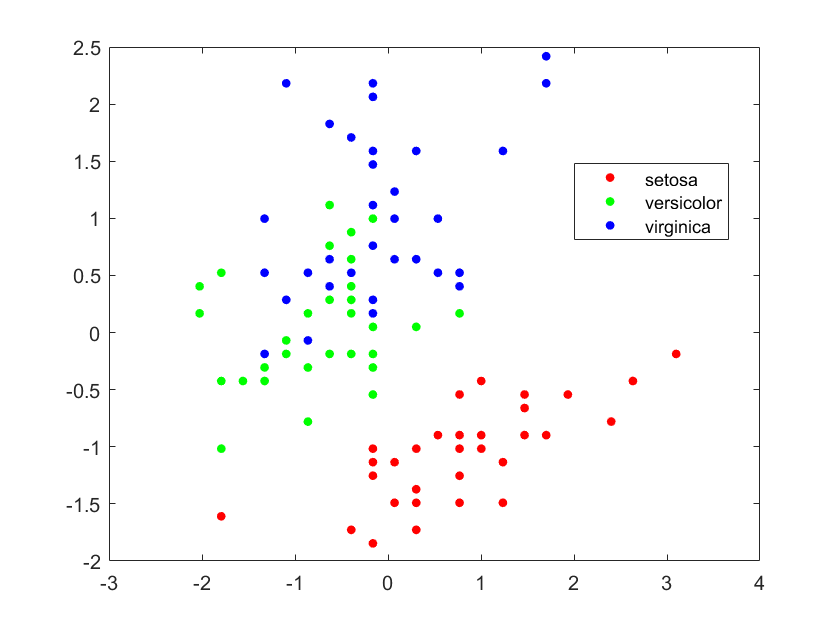

% call gscatter() to visualise all the data in one go:
gscatter(my_m.train_examples{:,'sepal_width'}, my_m.train_examples{:,'sepal_length'}, my_m.train_labels);

The plot should look familiar from the previous lab, but there are some subtle differences. Can you spot them before reading any further?

...

The two differences are:

- There are fewer points in total, because we're only showing the training examples this time (so about 75% of the data we looked at last time)

- The training examples have been standardised and so they have a slightly different range in x and y, for example some of the measurements are now negative so we know they can't be the original measurements (which are sizes)

We'll come back to understand more about the standardisation process later on.

## k-NN training: store the number of neighbours

The last step we need to focus on is that the `fit()` function takes a copy of the number of nearest neighbours we want to use during the classification phase. Again, we pass this number into the function, as its third argument, when we call it and it is referred to locally (within the scope of the function itself) as `k`. The number of nearest neighbours we want to use is copied into a field of the `m` structure called `k`.

Make sure you can find the line where this copy happens. Take time to add comments.

In the next section we move on to look at the steps involved in using our trained classifier for prediction.

## k-NN prediction: overview

The `predict()` function in the myknn class is reponsible for performing all the steps involved in prediction. Let's call it again:

% use our trained k-NN classifier to classify the testing data:
my_predictions = myknn.predict(my_m, test_examples);

classifying example example 1/38
classifying example example 2/38
classifying example example 3/38
classifying example example 4/38
classifying example example 5/38
classifying example example 6/38
classifying example example 7/38
classifying example example 8/38
classifying example example 9/38
classifying example example 10/38
classifying example example 11/38
classifying example example 12/38
classifying example example 13/38
classifying example example 14/38
classifying example example 15/38
classifying example example 16/38
classifying example example 17/38
classifying example example 18/38
classifying example example 19/38
classifying example example 20/38
classifying example example 21/38
classifying example example 22/38
classifying example example 23/38
classifying example example 24/38
classifying example example 25/38
classifying example example 26/38
classifying example example 27/38
classifying example example 28/38
classifying example example 29/38
classifying example exa

Have a look at the myknn class and make sure you can find the `predict()` function.

Here are the important steps that take place during prediction with the k-NN algorithm. After each one, in brackets, is a rough indication of how complicated that step is to understand, e.g. "easy", "moderately hard", etc:

Prediction

- Compute the distance between the new example we are trying to classify, and all of the examples in our training data (moderately hard)

- For the k training examples with the lowest distance scores, find the k corresponding class labels (moderately hard)

- Compute the mode (most common) class label across these k values to give a prediction (quite easy)

In the following sections we work through each of the steps in greater detail, looking at the corresponding lines of code in the myknn class. You should make sure you have the myknn class open ready to read and add your comments to, and you should make sure you look after your copy of the file carefully in between now and the in-class test.

## k-NN prediction: one testing example at a time

The first thing to notice is that the `predict()` function itself doesn't really do all that much...

The `predict()` function has been written to mimic the built-in Matlab function with the same name and it will accept as many different test examples as you want to want to pass it all bundled together in a single big table (the second argument of the function).

All it then does is to loop through all of the test examples in the table and call the `predict_one()` function on each one.* Remember there's one example per row in our tables, so to loop over the number of examples, we'd need to find the height of the table. We can get this with a call to `size(test_examples, 1)` and you should be able to identify the point where this call happens. You should also be able to identify the line of code that extracts a single example from the table, the line that passes it to `predict_one()`, and what happens to the result returned by `predict_one()`. Take time to add comments.

The next section moves on to look at the `predict_one()` function in more detail.

* Actually, it also applies standardisation to each one, but we've put standardisation on hold for now, and we'll come back to it at the end. We don't need to understand standardisation in order to understand the rest of the steps involved in prediction.

## k-NN prediction: compute distances

The first thing that `predict_one()` does with a testing example is to find the distance between it (that one testing example) and *all* of the training examples. It does this by calling the `calculate_distances()` function. Make sure you can find the line where this call happens. Take time to add a comment.

Next, we'll look at the `calculate_distances()` function in more detail...

The function `calculate_distances()` loops through all of the training examples stored in the model. This is similar to what happened in `predict()` but remember `predict()` was looping through the testing examples and `calculate_distances()` is looping through the training examples. Remember from our analysis of the training steps, above, that the training examples are stored in a field of the structure `m` called `train_examples`. Because there's one example on each row of that table, we can find the total number we need to loop over by calling `size(m.train_examples, 1)` and you should be able to identify the line where this happens.

On each iteration of the loop over the training examples, `calculate_distances()` is reading the next training example out of the `train_examples` table and calculating the distance between it (that single training example) and the test example. It does this by calling the `calculate_distance()` function.

Make sure you can find the line where the `calculate_distance()` function is called. You should also be able to identify the line of code that extracts a single example from the training data, and what happens to the result returned by `calculate_distance()`. Take time to add comments.

Next, we'll look at the `calculate_distance()` function in more detail...

The `calculate_distance()` function has the job of calculating the Euclidean or "straight-line" distance between any 2 examples. This calculation is fundamental to the k-NN algorithm, and this function is the "engine house" of the classifier, being used to compare every test example to every training example. The function treats the examples as single points in an N-dimensional feature space, where N is the total number of features. The equation for calculating the distance between any two points $p$ and $q$ is:


$$d=\sqrt{{\left(q_1 -p_1 \right)}^2 +{\left(q_2 -p_2 \right)}^2 +\;\ldotp \ldotp \ldotp +{\left(q_N -p_N \right)}^2 }$$


Don't worry if it looks complicated at first glance - it's not too bad. Do you remember the rule you learned at school for calculating the length of the longest side of a right-angled triangle (the "hypotenuse")? It said that all you have to do is to square the length of the two other sides, add them together and take the square root... The rule is sometimes called Pythagoras' Theorem and it's useful because it can give you the straight-line distance between any 2 points in a 2D space, when all you know is the coordinates of each point:

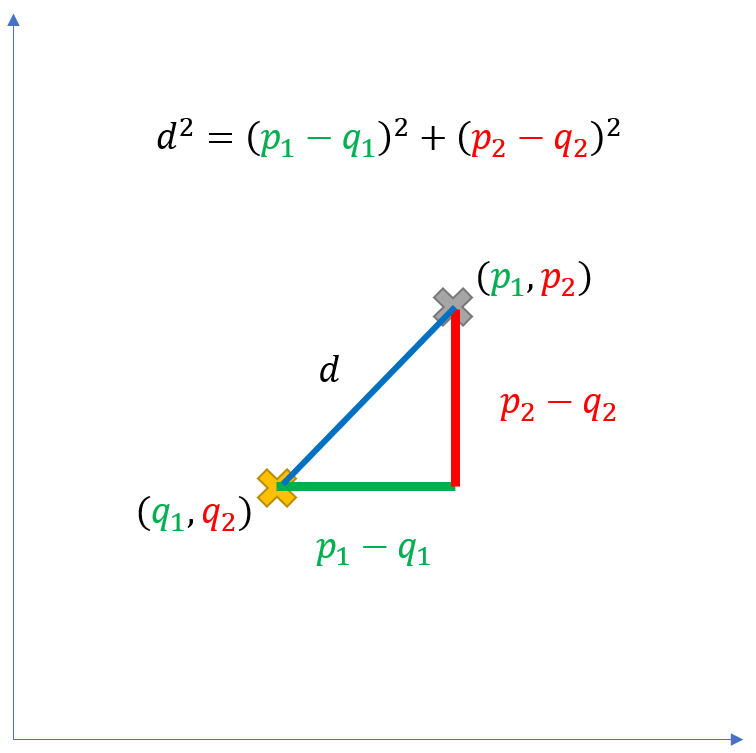

The measure $d$ is the one we want. It stands for "the distance between points p and q". And Pythagoras' Theorem tells us that:


$$d^2 ={\left(p_1 -q_1 \right)}^2 +{\left(p_2 -q_2 \right)}^2$$


We want to get rid of the square, so we take the square root of both sides of the equation:


$$d=\sqrt{{\left(p_1 -q_1 \right)}^2 +{\left(p_2 -q_2 \right)}^2 }$$


All that the equation for the Euclidean distance says is that this "trick" continues to work, no matter what the dimensionality of the space the points are in. Let's have another look at it:


$$d=\sqrt{{\left(q_1 -p_1 \right)}^2 +{\left(q_2 -p_2 \right)}^2 +\;\ldotp \ldotp \ldotp +{\left(q_N -p_N \right)}^2 }$$


So regardless of the number of dimensions of the space, N, you just take the difference between the coordinate of your two points in each dimension, square each of those differences, add them all up, and then take the square root.

The `calculate_distance()` function is performing all these same steps for us. Have a look at the function and check you can identify the basic steps involved.

Now let's have a closer look at `calculate_distance()` in action...

Let's find the distance between our first training example (this can be p) and our first testing example (this can be q):

% take the first training example:
p = train_examples{1,:}

p =     4.6000    3.4000    1.4000    0.3000


% take the first testing example:
q = test_examples{1,:}

q =     4.7000    3.2000    1.3000    0.2000


% find the Euclidean distance between the two points
distance = myknn.calculate_distance(p, q)

distance = 0.2646

Let's look at each of the individual steps that `calculate_distance()` performs:

First, we can take the difference between the coordinate of each point in each dimension with a simple subtraction (remember Matlab automatically subtracts two arrays element-by-element):

differences = q - p

differences =     0.1000   -0.2000   -0.1000   -0.1000


Next we can square all of these differences using the `.^` operator, which lets us raise numbers to a power (remember that when performing power operation on arrays, adding the `.` causes Matlab to perform the operation element-by-element):

squares = differences .^ 2

squares =     0.0100    0.0400    0.0100    0.0100


Next we can add up all of the numbers in our `squares` array by calling the `sum()` function:

total = sum(squares)

total = 0.0700

And, last of all, we can take the square root of the resulting value in `total` using the `sqrt()` function to give the final answer:

distance = sqrt(total)

distance = 0.2646

Check the answer matches with the one above. Check you can identify each of these steps happening inside the `calculate_distance()` function, and that you are happy with how they work. Take time to add comments.

Before you proceed to the next section, check that you can correctly calculate the Euclidean distance between the following two points *without calling* `myknn.calculate_distance()`:

p = [1 5 -2 -7]

p =      1     5    -2    -7


q = [-3 12 2 5]

q =     -3    12     2     5


% type your code on the lines below:
% (you should get the answer 15...)





## k-NN prediction: find the k nearest neighbours

So `calculate_distances()` loops through all of the training examples, calculating the distance between each one and the current test example, by making lots of calls to `calculate_distance()`. Once it has finished, it returns an array containing all of those distances to the function that called it: `predict_one()`. Make sure you can find this array, called `distances`, inside the `predict_one()` function. Take time to add comments.

The `calculate_distances()` function has created the `distances` array by looping through every row of the training examples table (stored in `m.train_examples`), in order. So the distances stored inside the `distances` array correspond with the rows of the training data. That is, the first distance corresponds to the first row, the second distance corresponds to the second, ..., the 100th distance corresponds to the 100th row. This is important for us to know because we need to understand which distance corresponds to which training example.

What we're really interested in is *which of the distances were shortest*? More specifically, we want to find the k shortest distances. In the experiments we've run above we've used k=10, so that would mean finding the 10 shortest distances. These correspond to the 10 training examples which lie closest to our testing example and are therefore *most similar* to it: its "nearest neighbours". To find these shortest distances we'll have to sort the `distances` array, but if we change the order of the distances inside our array then we risk losing track of which distance corresponds to which row in our training data table... Luckily, Matlab's `sort()` function anticipates this problem and can help us out. Let's investigate:

% make a "fake" array of made up distances:
distances = [2.5 1.2 3.21 0.6 3.20]

distances =     2.5000    1.2000    3.2100    0.6000    3.2000


% now sort them:
sorted_distances = sort(distances)

sorted_distances =     0.6000    1.2000    2.5000    3.2000    3.2100


So `sorted_distances` contains the values sorted into ascending order, and we can see that the smallest distance in our "fake" example data was 0.6. This is the distance to the nearest neighbour in all the training examples. That's great, but what we really want to know is which training example is that? We want to know which row of our training data table this winning distance of 0.6 corresponds to. That's more awkward. In this simple example we can look for it visually in the original `distances` array, and count up to find the index of the array element its sitting inside (it was in the 4th element of the original array, so the nearest neighbour was in the 4th row of the training data table)... For larger arrays we could probably write a loop to find the answer for us, but fortunately this is a relatively common problem, and Matlab's `sort()` function can return an extra parameter which makes things easy. As its second output, `sort()` returns an array holding, for each value in the sorted array, the index of the element it was stored inside in the original array. Let's try an example:

% make a "fake" array of made up distances:
distances = [2.5 1.2 3.21 0.6 3.20]

distances =     2.5000    1.2000    3.2100    0.6000    3.2000


% now sort them, and get their original indices:
[sorted_distances, indices] = sort(distances)

sorted_distances =     0.6000    1.2000    2.5000    3.2000    3.2100


indices =      4     2     1     5     3


The second array, which we've called `indices`, makes things much easier for us. If we want to know the original index of any value in the sorted array, we just look at the value inside the same element of the `indices` array. So the original index of the smallest distance (stored in the first element of `sorted_distances`) is:

indices(1)

ans = 4

The original index of the 2nd smallest distance (stored in the second element of `sorted_distances`) is:

indices(2)

ans = 2

The original index of the 5th smallest distance (stored in the fifth element of `sorted_distances`) is:

indices(5)

ans = 3

And so on...

This same approach is used by the myknn class when finding the k nearest neighbours for a single new testing example. This happens when `predict_one()` function calls the `find_nn_indices()` function and passes it the original array of `distances`. Make sure you can find both the line where this call happens and the `find_nn_indices()` function itself.

Notice that the `find_nn_indices()` function sorts the array of distances with `sort()` and asks for the second parameter, containing the original indices, just as we did above. It then reads out the first k original indices and returns them to `predict_one()`. These indices are the row numbers in the table of training data (stored in `m.train_examples`) of the k nearest neighbours to the current test example.

Make sure you're happy with how the `find_nn_indices()` function is working before you continue. Take time to add comments.

## k-NN prediction: compute a prediction

So `predict_one()` now knows the row numbers of the k nearest neighbours to the current testing example, and has them stored locally in an array. Make sure you can find this array, called `neighbour_indices`, inside the `predict_one()` function. Take time to add comments.

The final job that the `predict_one()` function has is to come up with a prediction about which class the current testing example belongs to. It does this based on which classes each of the test example's k nearest neighbours belong to. Remember that the array of class labels for the training data (stored inside `m.train_labels`) corresponds with the rows of the table containing the training examples. So the first class label corresponds to the example in the first row of the table. The second class label corresponds to the example in the second row of the table. And so on...

(Remember that when we "shuffle" the rows of the dataset to randomise their order, we shuffle it as a single big table that still includes the class labels, and so we don't lose this correspondence. Have another check of the shuffling code in the previous lab if you're not sure.)

So because we know the row numbers of the k nearest neighbours to the current testing example, we also know the elements in `m.train_labels` which contain their corresponding class labels.

The function `make_prediction()` looks up these corresponding class labels and calculates their mode (most common value) as a prediction of the most likely class for the current testing example. Make sure you can find both the line in `predict_one()` where the call to `make_prediction()` happens, and the `make_prediction()` function itself. Check you are happy with how `make_prediction()` is working. Take time to add comments.

## Standardisation of training data

The final thing we have to look at is standardisation. As we said above, this is probably the hardest step of the k-NN algorithm to understand. Don't worry, it's not that hard... But you should make sure you're confident with all the other aspects of the algorithm (covered in the earlier sections of this live script) before continuing with this section.

The first big job performed by the `fit()` function is to re-scale the values of each feature in the training data to lie within similar ranges. Let's call it again:

% train our own k-NN model:
my_m = myknn.fit(train_examples, train_labels, 10)

my_m = struct with fields:
              mean: [5.8580 3.0696 3.7527 1.1768]
               std: [0.8441 0.4293 1.7892 0.7535]
    train_examples: [112×4 table]
      train_labels: [112×1 categorical]
                 k: 10


This step is important because we don't want features that happen to contain very big values to dominate the Euclidean distance calculations that happen later on (versus features that happen to contain very small values). As a simple example, imagine the petal measurements in our irises data had been recorded in millimetres, but the sepal measurements had been recorded in centimetres. The petal features would contain much larger numbers than the sepal features, for no other reason than that a millimetre is a much smaller measure of distance than a centimetre. As a result, the (larger) petal features would dominate our distance calculations, with the values for the (smaller) sepal features not mattering as much. We don't want this kind of situation. Our starting assumption is that every feature is potentially just as important as any other, and so we re-scale the values of each feature to lie within similar ranges.

There are different options for doing this re-scaling. For example, "min-max normalisation" transforms data to lie between the values 0 and 1. But Matlab uses a slightly different approach called "z-score standardisation" which subtracts the mean value of the feature (so that the feature distribution is centred on zero) and divides by the standard deviation of the feature. Because the standard deviation gives a measure of the feature's "spread", features with a big spread get scaled down, and features with a small spread get scaled up. After performing z-score standardisation all feature distributions will have the same mean value (zero) and the same spread (standard deviation of 1). Z-score standardisation is a nice alternative to min-max normalisation because it better accommodates extreme (e.g., unusual or noisy) feature values.

Let's have a look at an example.

Let's recreate a slightly different version of the example we talked about above. Currently all the measurements in our data are in centimetres, but let's imagine that all the sepal lengths were recorded in millimetres instead. In the following lines of code we take a copy of the training examples to play around with, and multiply up every sepal length feature value by 10 (because there are 10 millimetres in 1 centimetre):

train_examples_fake = train_examples;
train_examples_fake{:,'sepal_length'} = train_examples_fake{:,'sepal_length'} .* 10;

Now let's plot the new sepal lengths against the sepal widths:

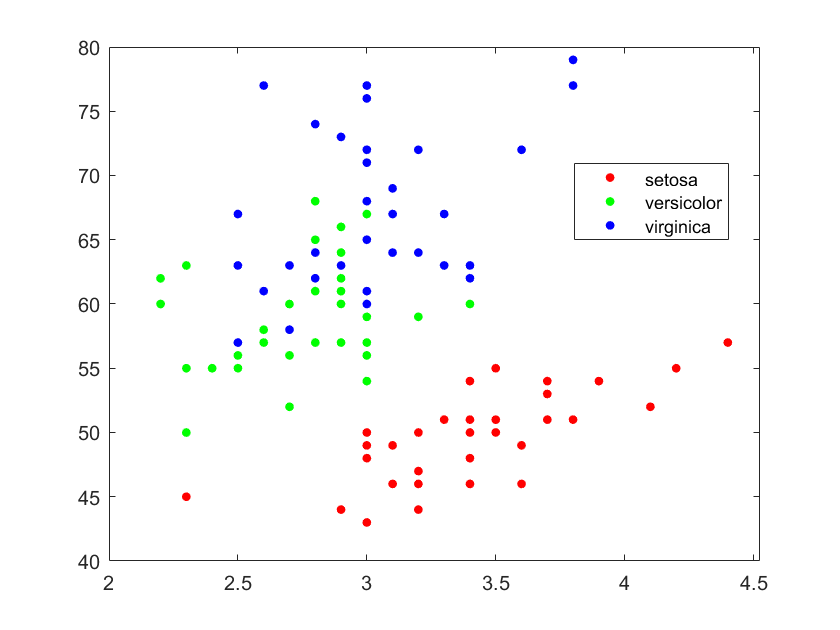

% call gscatter() to visualise all the data in one go:
gscatter(train_examples_fake{:,'sepal_width'}, train_examples_fake{:,'sepal_length'}, my_m.train_labels);

At first nothing looks very different from what we saw in the previous lab, but notice that the values on the y-axis are now much bigger (10 times as big). When we ask to plot data, Matlab tries to help us out by intelligently scaling the x- and y-axis so that the data we plot nicely fills the window. Notice here that it has "stretched out" the values from 2-4.5 on the x-axis to fill approximately as much space on the screen as the values from 40-80 do on the y-axis.

We can ask Matlab not to do this, and to keep the scales of the x- and y-axis equal with the function call `axis('equal')`. Let's try the same plot again using that extra command:

% call gscatter() to visualise all the data in one go:
gscatter(train_examples_fake{:,'sepal_width'}, train_examples_fake{:,'sepal_length'}, my_m.train_labels);
% set the axes to use the same scales:
axis('equal');

Now we can really see just how much larger the sepal length measurements (in mm) are than the sepal width measurements (in cm). Let's label the axes so there's no doubt:

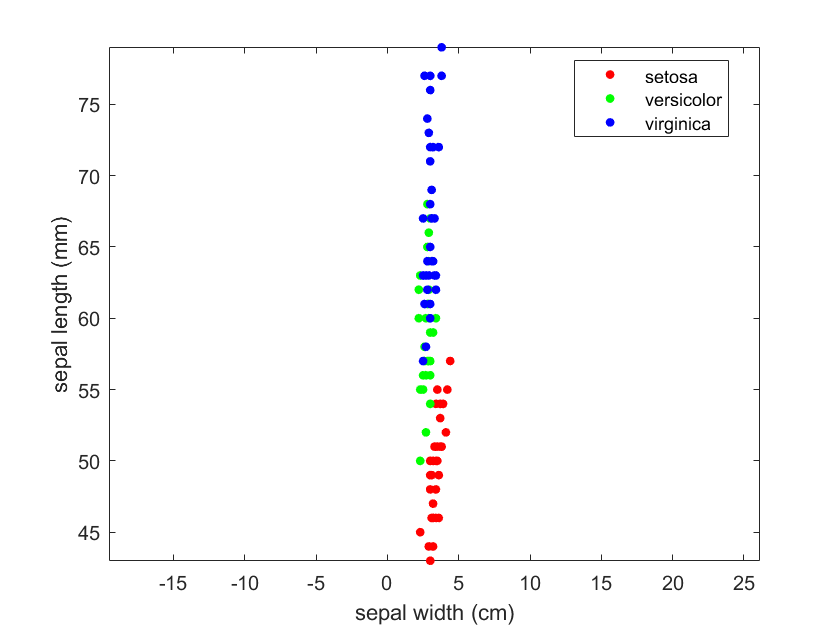

% label the axes for clarity:
xlabel('sepal width (cm)');
ylabel('sepal length (mm)');

If we were to go ahead and train a k-NN classifier using this data, it would perform poorly. This is because the sepal widths (and the petal lengths and petal widths) all contain very useful information that can be used to help discriminate between different classes, but this information is "drowned out" by the large numbers we have for the sepal lengths. These large numbers dominate the distance calculations we do when finding nearest neighbours.

For interest, let's use the built-in Matlab functionality we met in the previous lab to train a classifier *without* z-score standardisation, and test its performance:

% train the k-NN classifier on the training dataset:
m = fitcknn(train_examples_fake, train_labels, 'NumNeighbors', 10, 'Standardize', false)

m =   ClassificationKNN
           PredictorNames: {'sepal_length'  'sepal_width'  'petal_length'  'petal_width'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 112
                 Distance: 'euclidean'
             NumNeighbors: 10


  Properties, Methods


% now let's do the same thing with the test data (multiply sepal lengths by 10):
test_examples_fake = test_examples;
test_examples_fake{:,'sepal_length'} = test_examples_fake{:,'sepal_length'} .* 10;
% and see how it performs:
% use it to classify the testing dataset:
predictions = predict(m, test_examples_fake);
% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     10     2     0
     3     6     1
     1     8     7


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.6053

Notice the much lower classification accuracy...

The myknn class applies z-score standardisation to the training data and stores it inside a field of the resulting model structure called `train_examples`. Let's use our fake training data to re-train the `my_m` model and plot the standardised version of the data, again using the `axis('equal')` command, so we can see the difference:

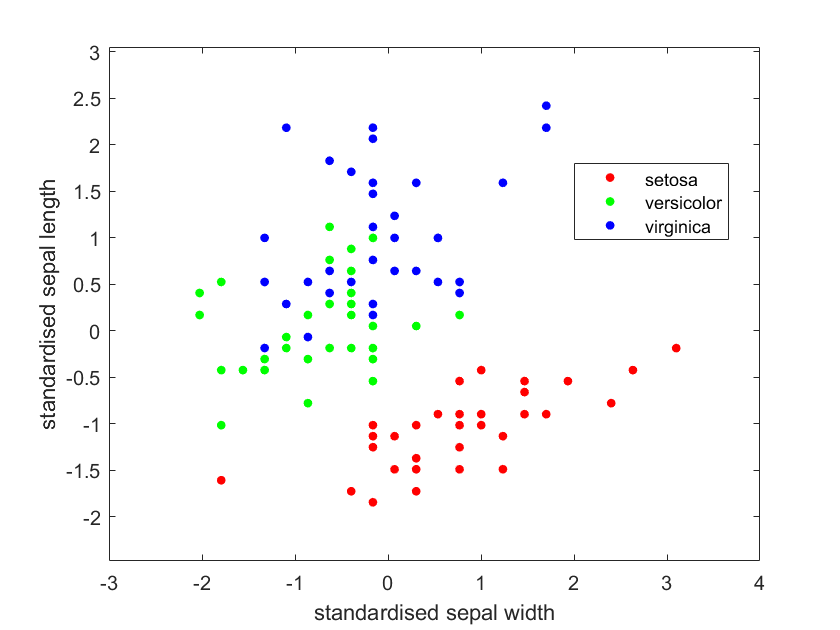

% re-train our k-NN model using the fake examples:
my_m = myknn.fit(train_examples_fake, train_labels, 10);

% call gscatter() to visualise all the data in one go:
gscatter(my_m.train_examples{:,'sepal_width'}, my_m.train_examples{:,'sepal_length'}, my_m.train_labels);
% set the axes to use the same scales:
axis('equal');

% label the axes for clarity:
xlabel('standardised sepal width');
ylabel('standardised sepal length');

Notice that the big scaling factor we applied to our sepal lengths (multiplying them by 10) has been removed. All feature values have had their mean (average) value subtracted so that they are centred on zero, and have been divided by their standard deviation (spread). 

These values are stored inside the model data, let's have a look at them. First, the original mean of every feature:

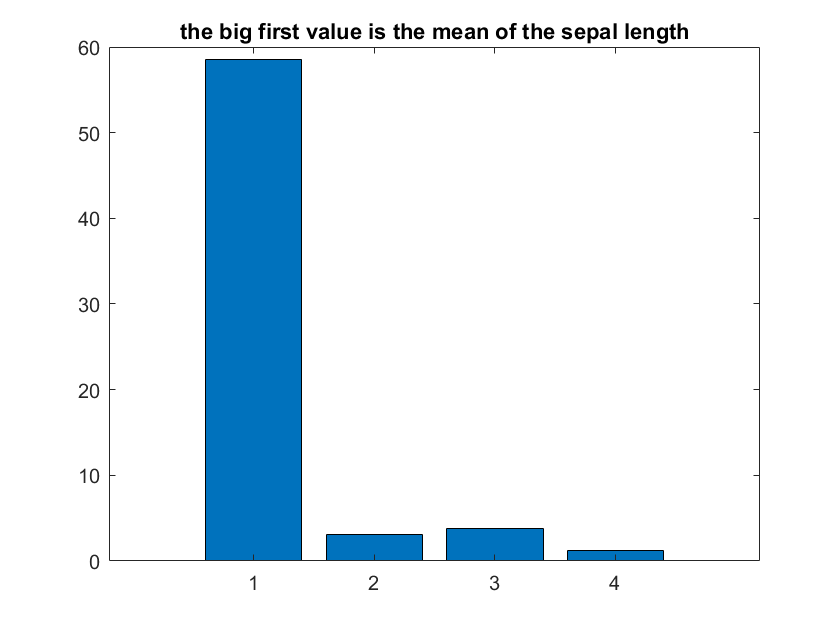

bar(my_m.mean);
title('the big first value is the mean of the sepal length');

Next the original standard deviation of every feature:

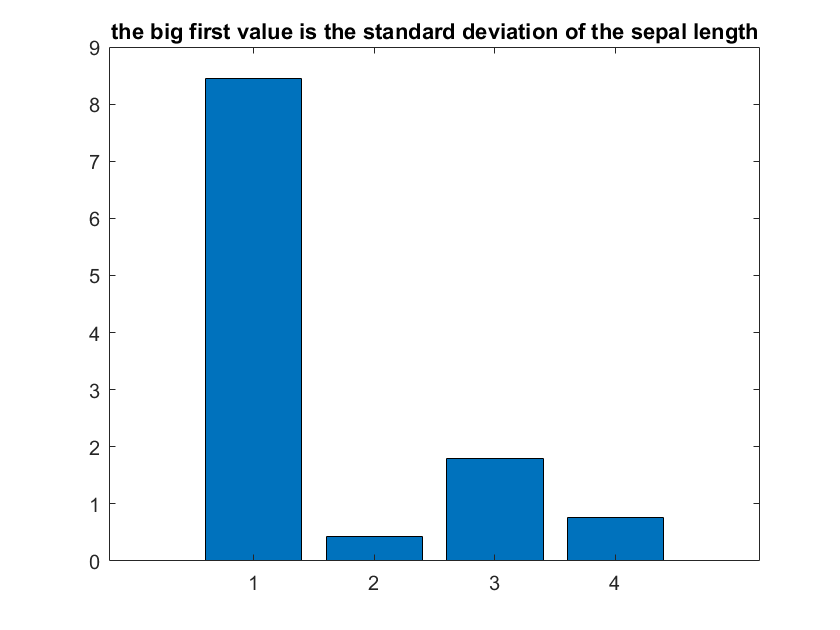

bar(my_m.std);
title('the big first value is the standard deviation of the sepal length');

Make sure you can identify the lines in the `fit()` function where the mean, standard deviation, and z-score standardisation calculations are happening. Not only the calls to `mean()` and `std()` themselves, but how the results are used to re-scale the training data. Take time to add comments.

Because standardisation subtracts the mean of the original feature values and then divides by their original standard deviation, it leaves no trace of the transformation we applied to our sepal lengths. Let's have a look at the mean and standard deviation of every feature stored in the model:

mean(my_m.train_examples{:,:})

ans = 	1.0e+-15 *

   -0.3588   -0.9615   -0.0912    0.5908


std(my_m.train_examples{:,:})

ans =     1.0000    1.0000    1.0000    1.0000


The new (standardised) means are almost exactly zero (the only error is due to tiny rounding errors in how accurately we can represent the true mean, before we subtract it). And the standard deviations are all one. These things will be true for any data that we standardise. 

## Standardisation of testing data

The final aspect of standardisation to consider is that if we apply any kind of transformation to our training examples, then, before we can try to classify any new test examples, we must make sure that we apply *the same transformation to them as well*.

So in the case of z-score standardisation this means subtracting the mean of the training data and dividing by the standard deviation of the training data. The need to use these values during the classification phase is the reason that we store the mean and standard deviation inside the model structure.

Make sure you can find the lines in the `predict()` function where the standardisation steps are applied to new testing examples. Take time to add comments.

So providing standardisation is switched on, the model trained/tested on `train_examples_fake`/`test_examples_fake` should perform identically to the model trained/tested on the original `train_examples`/`test_examples`. This is because standardisation performs a transformation that completely removes the "fake" scaling factor that we applied to the sepal lengths, and exactly the same transformation is later applied to any testing data. 

Let's check by using the model we trained on the fake training data to classify the fake test data:

% use it to classify the testing dataset:
my_predictions = myknn.predict(my_m, test_examples_fake);

classifying example example 1/38
classifying example example 2/38
classifying example example 3/38
classifying example example 4/38
classifying example example 5/38
classifying example example 6/38
classifying example example 7/38
classifying example example 8/38
classifying example example 9/38
classifying example example 10/38
classifying example example 11/38
classifying example example 12/38
classifying example example 13/38
classifying example example 14/38
classifying example example 15/38
classifying example example 16/38
classifying example example 17/38
classifying example example 18/38
classifying example example 19/38
classifying example example 20/38
classifying example example 21/38
classifying example example 22/38
classifying example example 23/38
classifying example example 24/38
classifying example example 25/38
classifying example example 26/38
classifying example example 27/38
classifying example example 28/38
classifying example example 29/38
classifying example exa

% output a confusion matrix:
[c,order] = confusionmat(test_labels, my_predictions)

c =     12     0     0
     0    10     0
     0     4    12


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
my_p = sum(diag(c)) / sum(c(1:1:end))

my_p = 0.8947

Notice we get the same classification accuracy we did with the original data.

## Tasks

Review your copy of the myknn class and check you are happy with the overall standard of the commenting:

- If you forget a detail about k-NN classification under the pressure of the in-class test conditions, are your comments good enough to help you figure it out?

- Have you commented each line of code? (Or some comments adequately cover multiple lines of code)

- Have you included overview comments above each of the functions?

- Have you focused on the *why* rather than the *what*? (see also the "Writing good comments" document on Moodle)